# Patrones Locales Binarios (LBP)

En este ejemplo, vamos a analizar la textura de una imágen usando el descriptor LBP. En Matlab, tenemos la función `extractLBPFeatures `que permite extraer el descriptor LBP de una imagen en gris.

Usaremos 3 imágenes de textura disponible en Matlab.

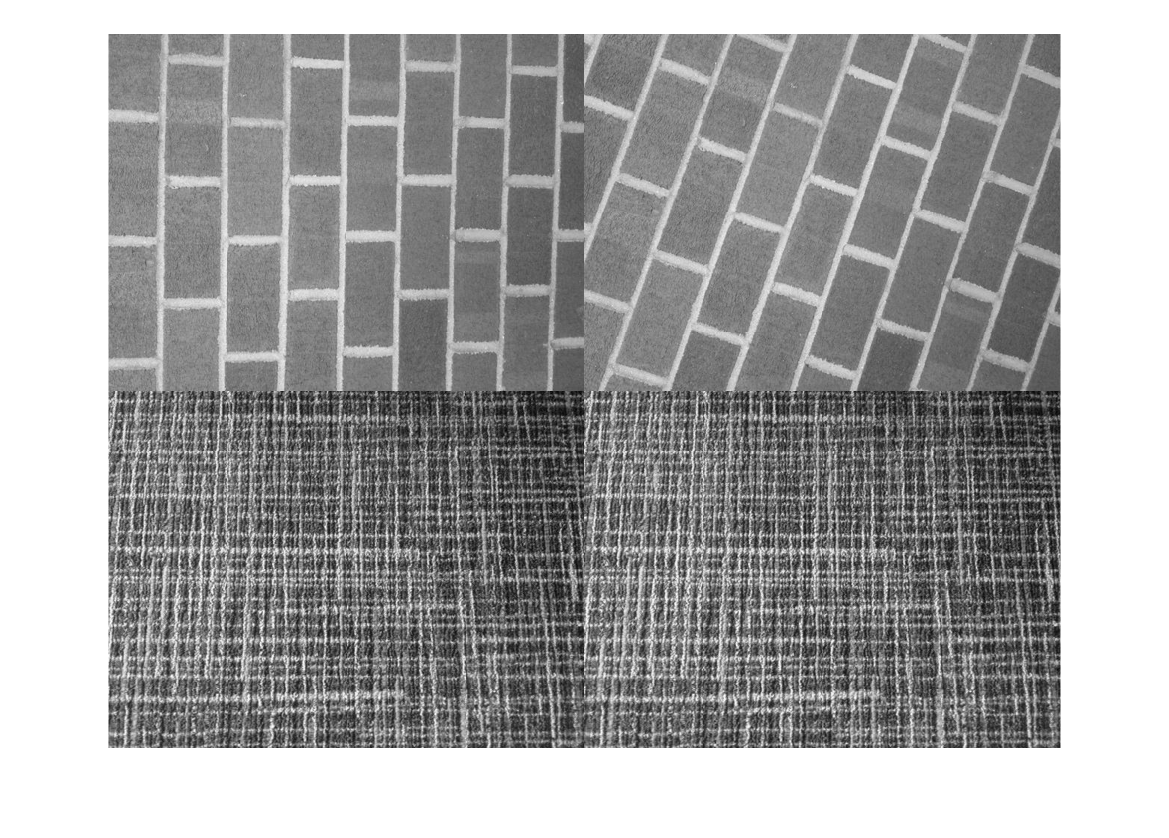


% Abrimos la imagen "briks.jpg" disponible en Matlab
brickWall = imread('bricks.jpg');

% Abrimos la imagen "bricksRotated.jpg" que es una versión rotada de la imagen "briks.jpg"
rotatedBrickWall = imread('bricksRotated.jpg');

% Abrimos la imagen 'carpet.jpg'
carpet = imread('carpet.jpg');


figure
montage({brickWall,rotatedBrickWall,carpet,carpet})

Por defecto, la función "`extractLBPFeatures`" utiliza **8 vecinos** y un **radio **`r=1`. El argumento "Upright" toma los valores "true" o "false". 

- Si "Upright"=true, el algoritmo genera un descriptor LBP uniforme (**invariante a la rotación**). En este caso, el tamaño del descriptor es 59.

- Si "Upright"=false, el algoritmo genera un descriptor LBP clásico que no es invariante a la rotación

# Descriptor LBP invariante a la rotación

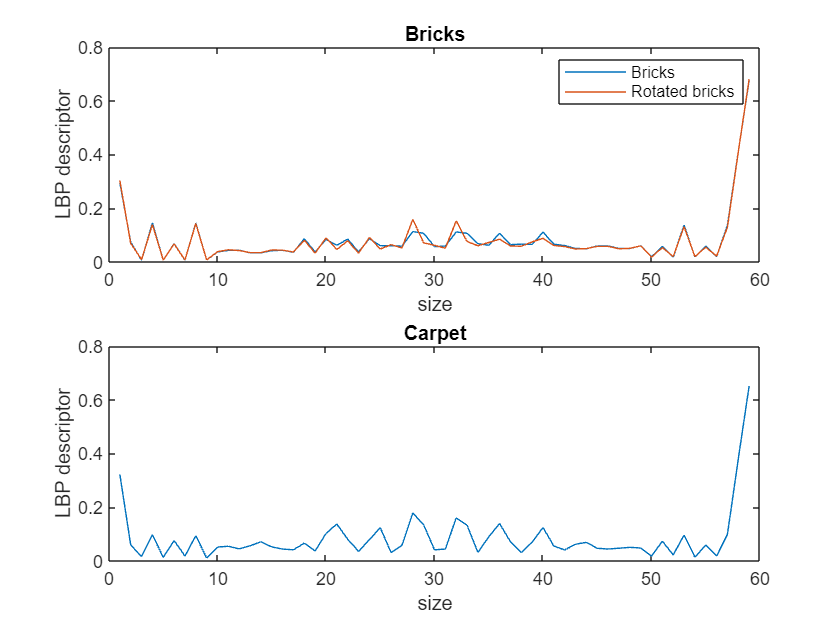

% Calculamos los descriptores LBP
% Por defecto, la función "extractLBPFeatures" utiliza 8 vecinos y un radio
% r=1. El argumento "Upright" toma los valores "true" o "false". Si
% "Upright"=true, el algoritmo genera un descriptor LBP uniforme
% (invariante a la rotación), en caso contrario, genera un descriptor LBP
% clásico que no invariante a la rotación

lbpBricks1_u = extractLBPFeatures(brickWall,'Upright',true);
lbpBricks2_u = extractLBPFeatures(rotatedBrickWall,'Upright',true);
lbpCarpet_u = extractLBPFeatures(carpet,'Upright',true);

close all
figure(1)
subplot(211)
plot(lbpBricks1_u);hold on
plot(lbpBricks2_u)
xlabel('size')
ylabel('LBP descriptor')
legend('Bricks','Rotated bricks')
title('Bricks')
subplot(212)
plot(lbpCarpet_u)
xlabel('size')
ylabel('LBP descriptor')
title('Carpet')

Cómo se puede apreciar en la gráfica de arriba, el operador LBP generar un descriptor que es invariante a la rotación que hemos aplicado a la imágen de "Bricks". Excepto en algunos puntos, los descriptores de los "bricks" son muy similares.

Calcular la similitud entre los descriptores 

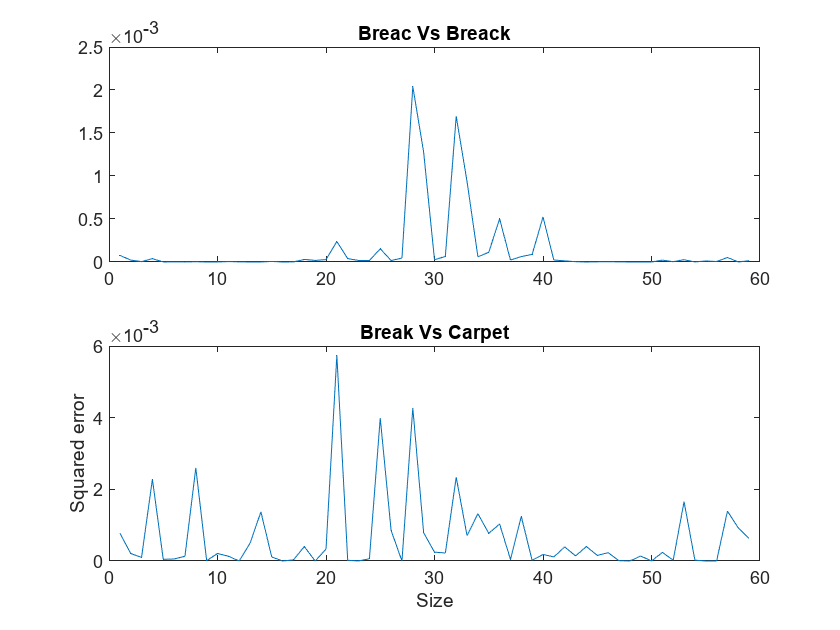

brickVsBrick_u = (lbpBricks1_u - lbpBricks2_u).^2;
brickVsCarpet_u = (lbpBricks1_u - lbpCarpet_u).^2;

close all
figure(2)
subplot(211)
plot(brickVsBrick_u);
title('Breac Vs Breack')
subplot(212)
plot(brickVsCarpet_u)
xlabel('Size')
ylabel('Squared error')

title('Break Vs Carpet')

# Descriptor LBP no-invariante a la rotación

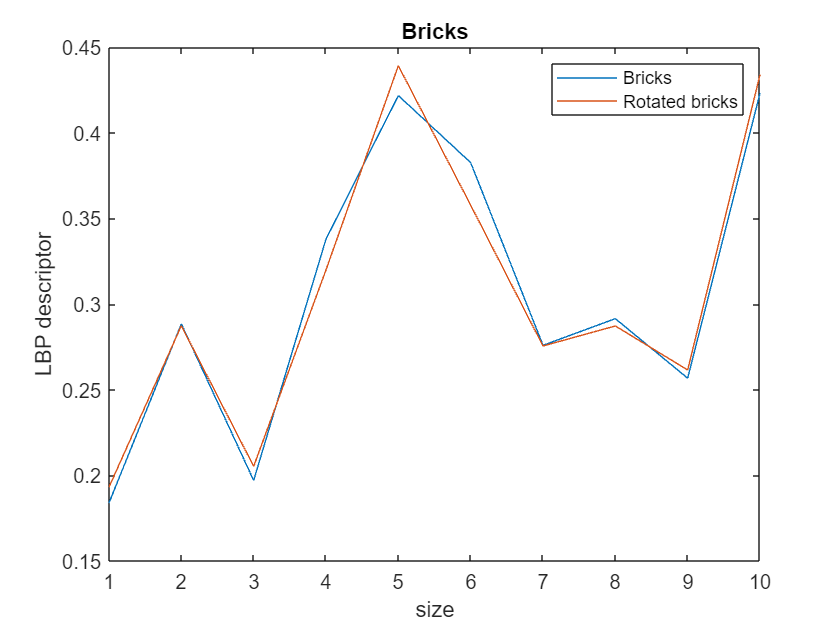

% Calculamos los descriptores LBP
% Por defecto, la función "extractLBPFeatures" utiliza 8 vecinos y un radio
% r=1. El argumento "Upright" toma los valores "true" o "false". Si
% "Upright"=true, el algoritmo genera un descriptor LBP uniforme
% (invariante a la rotación), en caso contrario, genera un descriptor LBP
% clásico que no invariante a la rotación

lbpBricks1_nu = extractLBPFeatures(brickWall,'Upright',false);
lbpBricks2_nu = extractLBPFeatures(rotatedBrickWall,'Upright',false);

close all
figure(1)
plot(lbpBricks1_nu);hold on
plot(lbpBricks2_nu)
xlabel('size')
ylabel('LBP descriptor')
legend('Bricks','Rotated bricks')
title('Bricks')

brickVsBrick_nu = (lbpBricks1_nu - lbpBricks2_nu).^2;



Calcular la similitud entre los descriptores 

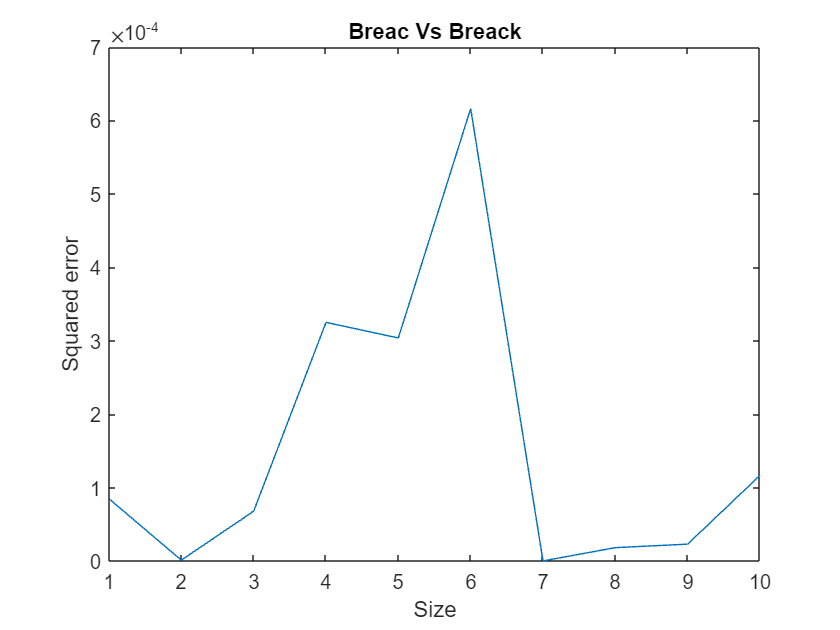


close all
figure()
plot(brickVsBrick_nu);hold on
xlabel('Size')
ylabel('Squared error')
title('Breac Vs Breack')